## Lab 3

First import Quanser set of data

QuanserData;

### Question 1, 2, 3, 4

paper

### Question 5

Find the equilibrium point for a constant input V=10V. (function trim)

Set initial values (or not: in that case use [ ] )

x0=[];u0=10;y0=[];

Select the index of states and/or states which are to be freezed:

ix=[];
iu=1;
iy=[];

Find the equilibrium point:

[xtrim,utrim,ytrim,dxtrim] = trim('Electrical',x0,u0,y0,ix,iu,iy)

xtrim =   224.4221
    0.0684


utrim = 10

ytrim =     0.0191
  224.4221
    0.0684


dxtrim = 	1.0e+-8 *

   -0.0524
    0.2112


### Question 6

Find the linearized model at the equilibrium point. (function linmod)

[A,B,C,D] = linmod('Electrical', xtrim, utrim)

A = 	1.0e+03 *

   -0.0012    3.7490
   -0.0362   -7.2414


B =          0
  862.0690


C =     0.0003         0
    1.0000         0
         0    1.0000


D =      0
     0
     0


Create a state space model and a transfer function model

Gss=ss(A,B,C,D);
Gss=Gss(1,1);
Gtf=tf(Gss)

Gtf =
 
             
          843
             
  -------------------
                     
  s^2 + 7243 s       
                     
           + 1.445e05
                     
 
Continuous-time transfer function.



damp(Gtf)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.00e+01     1.00e+00       2.00e+01         5.00e-02    
 -7.22e+03     1.00e+00       7.22e+03         1.38e-04    


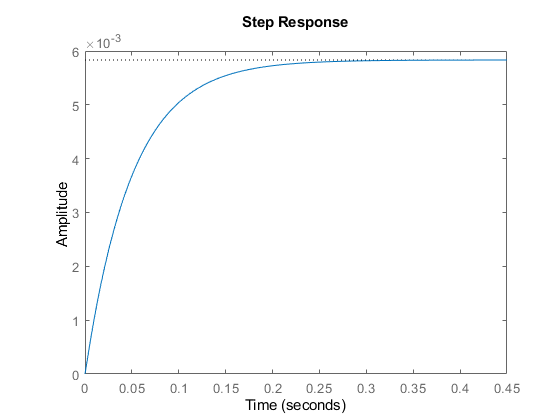

step(Gtf)

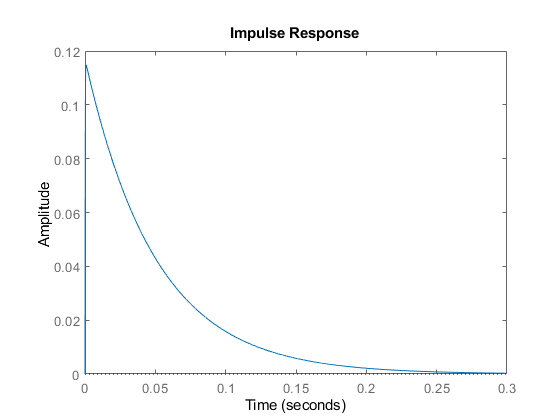

impulse(Gtf)

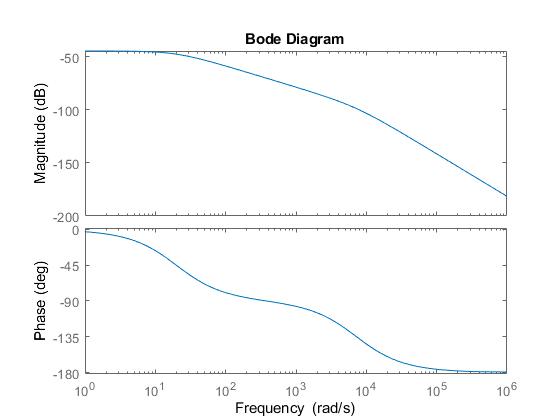

bode(Gtf)

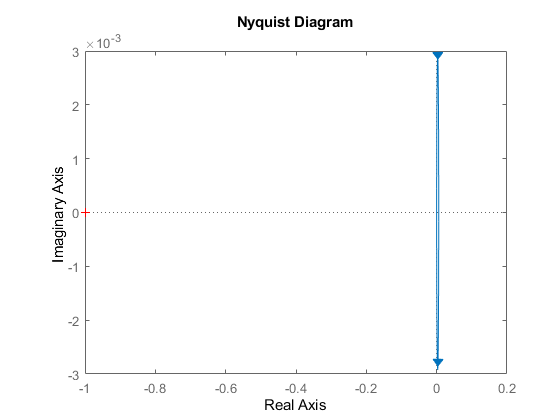

nyquist(Gtf)

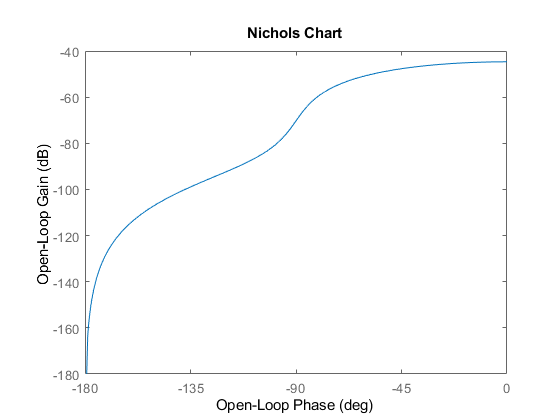

nichols(Gtf)

pole(Gtf)

ans = 	1.0e+03 *

   -7.2226
   -0.0200


zero(Gtf)


ans =

  0×1 empty double column vector



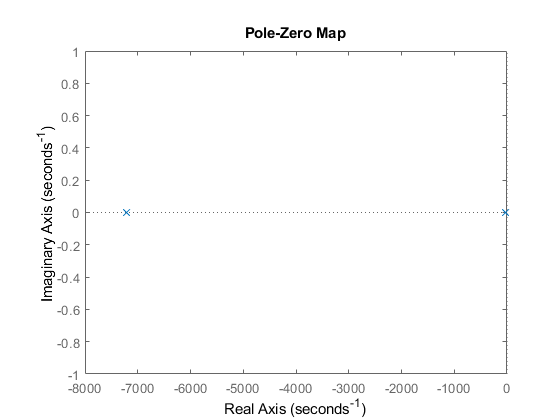

pzmap(Gtf)

### Question 7

step, impulse, bode, nyquist, nichols, pole, zero, damp, pzmap, etc.

### Question 8

Create the full simulation model Mechanical.slx

Extract and examine the state structure of the model:

x = Simulink.BlockDiagram.getInitialState('Mechanical')

x = Simulink.SimulationData.Dataset 'xFinal' with 6 elements

                        Name  BlockPath                     
                        ____  _____________________________ 
    1  [1x1 State]      ''    Mechanical/Integrator        
    2  [1x1 State]      ''    Mechanical/Integrator1       
    3  [1x1 State]      ''    Mechanical/Motor1/Integrator 
    4  [1x1 State]      ''    Mechanical/Motor1/Integrator1
    5  [1x1 State]      ''    Mechanical/Motor2/Integrator 
    6  [1x1 State]      ''    Mechanical/Motor2/Integrator1

  - Use braces { } to access, modify, or add elements using index.


### Question 9

Find the equilibrium point:

x0=[];u0=0;y0=[];
ix=[];
iu=1;
iy=[];
[xtrim,utrim,ytrim,dxtrim] = trim('Mechanical',x0,u0,y0,ix,iu,iy)

xtrim =     0.0000
  224.4221
  224.4221
   -0.0000
    0.0684
    0.0684


utrim = 1.4823e-21

ytrim = 9.2360e-13

dxtrim = 	1.0e+-8 *

   -0.0000
   -0.0004
   -0.0004
   -0.0003
   -0.1628
   -0.0031


### Question 10

Find the linearized model

[A,B,C,D] = linmod('Mechanical', xtrim, utrim)

A = 	1.0e+03 *

         0         0         0    0.0010         0         0
         0   -0.0012         0         0    3.7490         0
         0         0   -0.0012         0         0    3.7490
   -0.0037    0.0000   -0.0000   -0.0003         0         0
         0   -0.0362         0         0   -7.2414         0
         0         0   -0.0362         0         0   -7.2414


B =          0
         0
         0
         0
  862.0690
 -862.0690


C =      1     0     0     0     0     0


D = 0

Gmec = ss(A,B,C,D)

Gmec =
 
  A = 
              x1
   x1          0
   x2          0
   x3          0
   x4     -3.726
   x5          0
   x6          0
 
              x2
   x1          0
   x2     -1.213
   x3          0
   x4   0.001917
   x5     -36.21
   x6          0
 
              x3
   x1          0
   x2          0
   x3     -1.213
   x4  -0.001917
   x5          0
   x6     -36.21
 
              x4
   x1          1
   x2          0
   x3          0
   x4    -0.3302
   x5          0
   x6          0
 
              x5
   x1          0
   x2       3749
   x3          0
   x4          0
   x5      -7241
   x6          0
 
              x6
   x1          0
   x2          0
   x3       3749
   x4          0
   x5          0
   x6      -7241
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4       0
   x5   862.1
   x6  -862.1
 
  C = 
       x1  x2
   y1   1   0
 
       x3  x4
   y1   0   0
 
       x5  x6
   y1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-spa

### Question 11

Compute controlability matrix

Co = ctrb(A,B);
Ob = obsv(A,C);

Determine the number of uncontrollable states.

unco = length(A) - rank(Co)

unco = 4

unob = length(A) - rank(Ob)

unob = 2

Do the same for governability

zpk(Gmec)

ans =
 
                           
        12390 (s+20.01)    
                           
                   (s+7223)
                           
  -------------------------------
                                 
  (s+20.01)^2                    
                                 
          (s+7223)^2             
                                 
          (s^2 + 0.3302s + 3.726)
                                 
                                 
 
Continuous-time zero/pole/gain model.




tol=1e-6;
unco = length(A) - rank(Co,tol)

unco = 1

unob = length(A) - rank(Ob,tol)

unob = 2

### Question 12

Use minreal to obtain the pole-zero cancelled transfer function

Gmec_reduced=minreal(Gmec)

2 states removed.

Gmec_reduced =
 
  A = 
               x1
   x1      -1.213
   x2       36.21
   x3   -0.002703
   x4   0.0002048
 
               x2
   x1       -3749
   x2       -7241
   x3   1.873e-08
   x4  -1.399e-09
 
               x3
   x1   7.944e-09
   x2    1.53e-08
   x3      -0.123
   x4     -0.9907
 
               x4
   x1    3.39e-09
   x2   6.629e-09
   x3       3.735
   x4     -0.2072
 
  B = 
               u1
   x1  -8.705e-26
   x2       -1219
   x3   2.582e-09
   x4   1.102e-09
 
  C = 
               x1
   y1  -2.044e-12
 
               x2
   y1   1.061e-12
 
               x3
   y1     0.07556
 
               x4
   y1      0.9971
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



zpk(Gmec_reduced)

ans =
 
                    
               12390
                    
  -------------------------------
                                 
  (s+7223)                       
                                 
          (s+20.01)              
                                 
          (s^2 + 0.3302s + 3.726)
                                 
                                 
 
Continuous-time zero/pole/gain model.



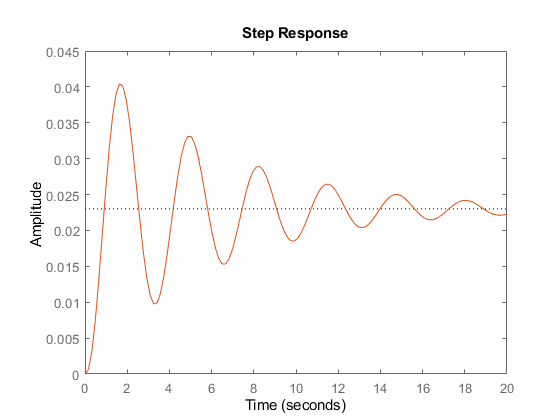

step(Gmec,Gmec_reduced,20)